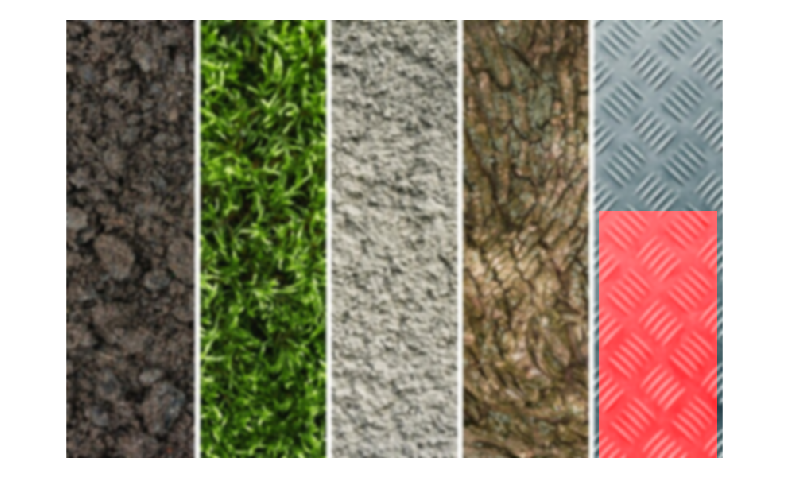

clear
close

smallorig = imread('guixmini.jpg'); 
bigorig = imread('textures.jpg');
lim=1;
pas=10;

% Preprocess
% Aplicar filtro gaussiano para homogeneizar
small = imgaussfilt(smallorig,2);
big = imgaussfilt(bigorig,2);

% Convertir big a RGB si es en escala de grises
if size(big, 3) == 1
    big = repmat(big, [1 1 3]);
end

% Extraer características de textura de la imagen pequeña
small_features = extract_textural_features(small);

% Configurar parámetros de la ventana deslizante
window_size = size(small);
step_size = pas; % Tamaño del paso de la ventana deslizante

% Inicializar una máscara binaria para almacenar las regiones detectadas
mask = false(size(big, 1), size(big, 2));

% Recorrer la imagen grande con la ventana deslizante
for i = 1:step_size:size(big, 1) - window_size(1) + 1
    for j = 1:step_size:size(big, 2) - window_size(2) + 1
        % Extraer una región de la imagen grande
        region = big(i:i+window_size(1)-1, j:j+window_size(2)-1, :);
        
        % Calcular características de textura de la región
        region_features = extract_textural_features(region);
        
        % Calcular la distancia entre las características de la región y las características de la imagen pequeña
        distancia = dist(region_features, small_features);
        
        % Si la distancia es menor que un cierto umbral, considerar la región como similar
        if distancia < lim % Umbral
            % Marcar la región en la máscara binaria
            mask(i:i+window_size(1)-1, j:j+window_size(2)-1) = true;
        end
    end
end

% Crear una imagen en color para la superposición
overlay = cat(3, ones(size(big, 1), size(big, 2)) * 255, zeros(size(big, 1), size(big, 2)), zeros(size(big, 1), size(big, 2))); % Red overlay

% Convertir las imágenes a tipo double para realizar las operaciones de superposición
big_rgb = im2double(big);
overlay = im2double(overlay);

% Aplicar la máscara a la superposición y combinarla con la imagen original
alpha = 0.2; % Opacidad del marcaje
marked_image = big_rgb;
for c = 1:3
    marked_image(:,:,c) = big_rgb(:,:,c) .* ~mask + overlay(:,:,c) .* mask * alpha + big_rgb(:,:,c) .* mask * (1 - alpha);
end

% Mostrar la imagen marcada
imshow(marked_image);